## Load and Process MRIs

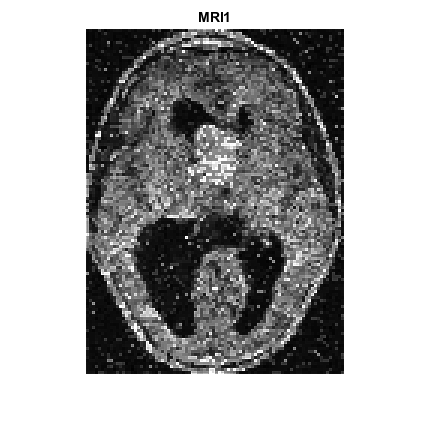

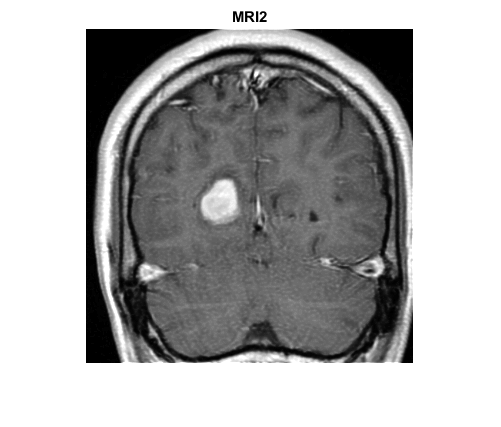

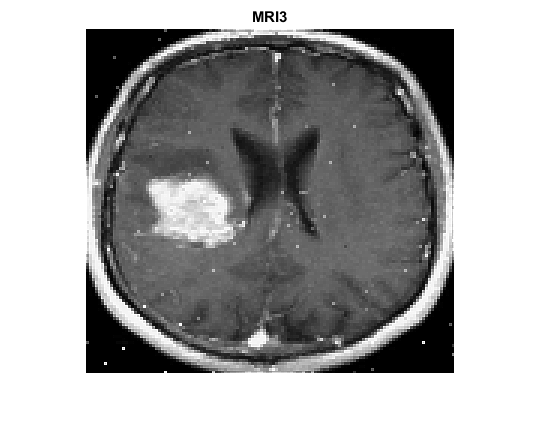

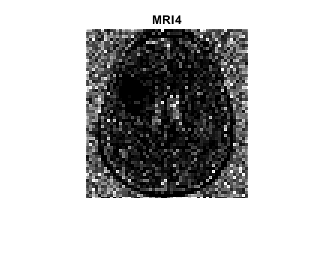

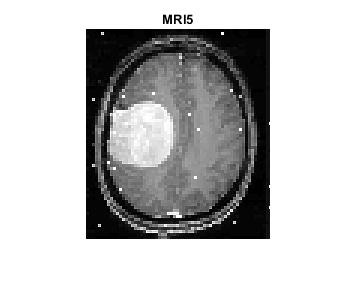

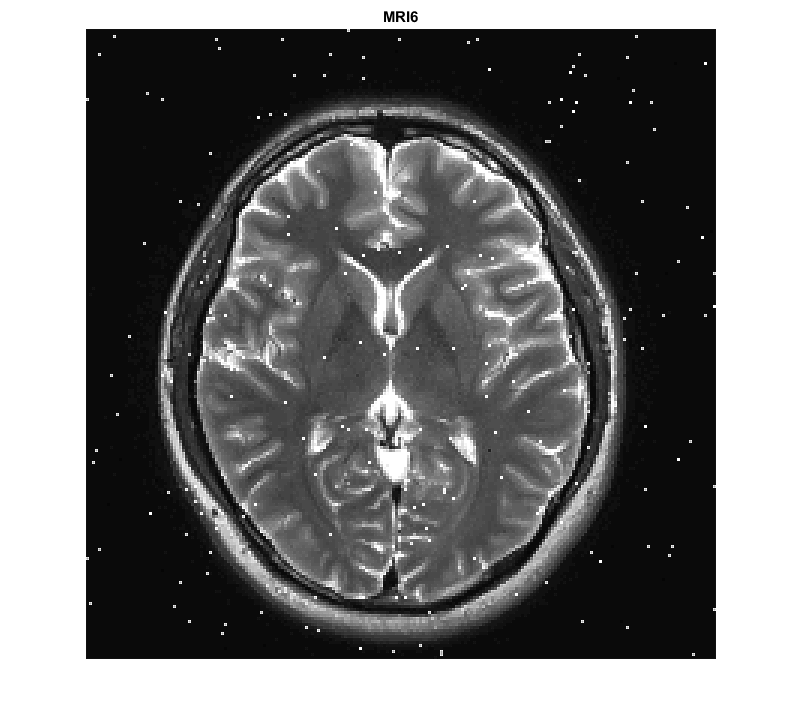

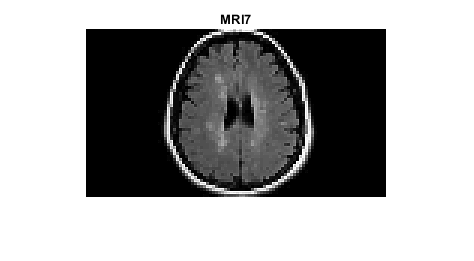

clear;

% Load MRIs & tumors
MRIs = cell(1,7);
for i=1:7
    MRIs{i} = rgb2gray(imread(strcat('MRIs\mri',num2str(i),'D.png')));
end

tumors = cell(1,5);
for i=1:5
    tumors{i} = rgb2gray(imread(strcat('tumors\tumor',num2str(i),'.png')));
end

% Preprocess MRIs
MRIs = preprocess_mris(MRIs);

% Display processed images
for i=1:7
    figure; imshow(MRIs{i}); title(strcat("MRI", num2str(i)));
end

## Detect Tumors

This MRI scan contains a tumor.


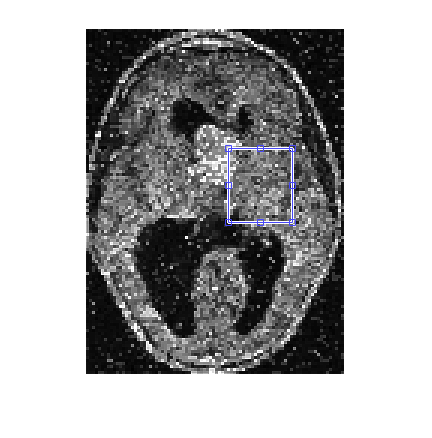

detect_tumor(MRIs{1},tumors);

This MRI scan contains a tumor.


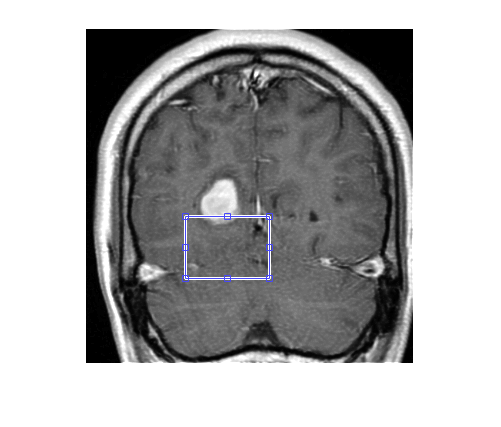

detect_tumor(MRIs{2},tumors);

This MRI scan contains a tumor.


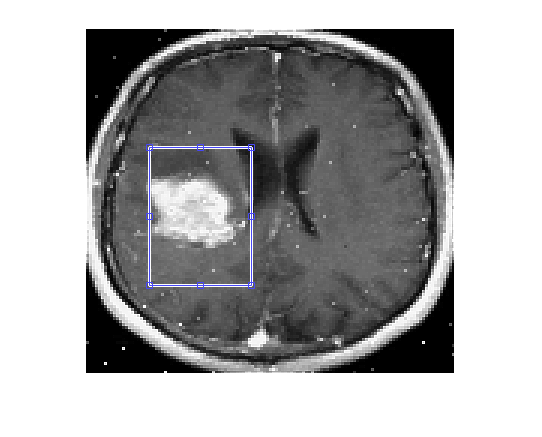

detect_tumor(MRIs{3},tumors);

This MRI scan contains a tumor.


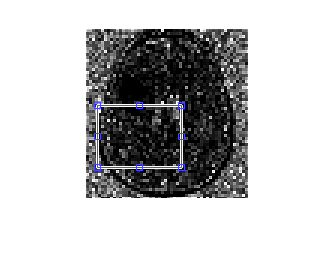

detect_tumor(MRIs{4},tumors);

detect_tumor(MRIs{5},tumors);

This MRI scan does not contain any tumors.


This MRI scan contains a tumor.


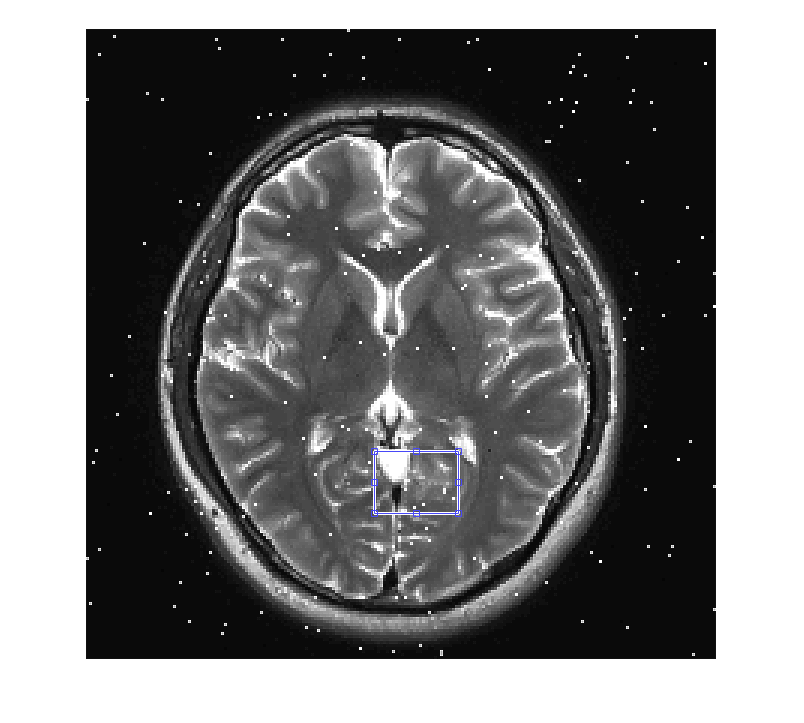

detect_tumor(MRIs{6},tumors);

detect_tumor(MRIs{7},tumors);

This MRI scan does not contain any tumors.


# External Functions

function MRIs = preprocess_mris(MRIs)

% MRI Scan 1
opened = imopen(MRIs{1},ones(2,3));
filt = median_filt(median_filt(opened));
sharpened = sharpen(filt,3,1);
MRIs{1} = contrast_stretch(sharpened);

% MRI Scan 2
sharpened = sharpen(MRIs{2},3,1);
MRIs{2} = contrast_stretch(sharpened);

% MRI Scan 3
filt = median_filt(MRIs{3});
sharpened = sharpen(filt,3,1);
MRIs{3} = contrast_stretch(sharpened);

% MRI Scan 4
complemented = imcomplement(MRIs{4});
filt = median_filt(median_filt(complemented));
sharpened = sharpen(filt,3,1);
MRIs{4} = contrast_stretch(sharpened);

% MRI Scan 5
filt = median_filt(median_filt(MRIs{5}));
sharpened = sharpen(filt,3,1);
MRIs{5} = contrast_stretch(sharpened);

% MRI Scan 6
filt = median_filt(median_filt(MRIs{6}));
sharpened = sharpen(filt,3,1);
MRIs{6} = contrast_stretch(sharpened);

% MRI Scan 7
filt = median_filt(MRIs{7});
sharpened = sharpen(filt,3,1);
MRIs{7} = contrast_stretch(sharpened);

end

function out = sharpen(img, kernel_size, factor)
% sharpening using mean subtraction

kernel = ones(kernel_size) ./ (kernel_size^2);
averaged = conv2(img, kernel, 'same');

edges = uint8(img) - uint8(averaged);
out = uint8(img) + edges.*factor;

end

function out = median_filt(img)
% simple 3x3 median filter

median_fn = @(block) median(block.data(:)) * ones(size(block.data), class(block.data));
out = blockproc(single(img), [3 3], median_fn);

end

function out = contrast_stretch(img)
% apply contrast stretching using histogram equalization

old = stretchlim(img);
old_min = old(1);
old_max = old(2);
new_min = 0;
new_max = 1;

out = new_min + (img-old_min) .* ((new_max-new_min) ./ (old_max-old_min));

end

function detect_tumor(mri, tumors)
% search for every tumor in tumors inside the MRI scan

corr_thresh = 0.3;

mean_corr = zeros(1,5);
for t=1:5
    tumor = tumors{t};
    c = fft_corr(mri, tumor);
    mean_corr(t) = mean(c(:));
end

if(max(mean_corr)>corr_thresh)
    disp('This MRI scan contains a tumor.')
    draw_rect(fft_corr(mri, tumor), mri, tumors{mean_corr==max(mean_corr)})
else
    disp('This MRI scan does not contain any tumors.')
end

end

function draw_rect(c, mri, tumor)
% Draw boundaries around the tumor

[ypeak, xpeak] = find(c==max(c(:)));

yoffSet = ypeak-size(tumor,1);
xoffSet = xpeak-size(tumor,2);

figure
imshow(mri);
imrect(gca, [xoffSet+1, yoffSet+1, size(tumor,2), size(tumor,1)]);

end

function c = fft_corr(mri,tumor)
% 2D cross-correlation with FFT

% Matrix dimensions
size_a = size(mri);
size_b = size(tumor);

% Cross-correlation dimensions
size_c = size_a+size_b-1;
bpad = zeros(size_c);
apad = zeros(size_c);
apad(1:size_a(1),1:size_a(2)) = mri;
bpad(1:size_b(1),1:size_b(2)) = tumor(end:-1:1,end:-1:1);
fft_a = fft2(apad);
fft_b = fft2(bpad);
c = real(ifft2(fft_a.*fft_b));
c = c/max(c(:));

end